%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%  EC516 Project 01  %%%
%%% Jeremiah Sullivan  %%%
%%%    ML, IC, or RL   %%% 
%%%   November 2018    %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Project Requirements
% (a)	Record and display a speech signal
% (b)	(3 points) Compute and display the discrete TDFT of the	
%           rectangular	(“box”)	window, duration ~20 ms.


% (c)	(4 points) Use GFBS Method to compute signal back from discrete TDFT
clc; clear all; close all;

## A: Record and display signal

Traditionally sample rate is set by analog (or physical) low-pass filters

Choosing to use 2013 13" Macbook Pro // Bose Headphones as a recording platform of convenience. Sticking to default sampling rates, can later decimate if desired. Standard 3.5 mm audio connector, so assuming the Mac handles all active conditioning. Not using the "noise-cancelling" mode on the headphone, because I bet this geometry would cause... unique... problems with the algorithms. May be interesting to try later though. 

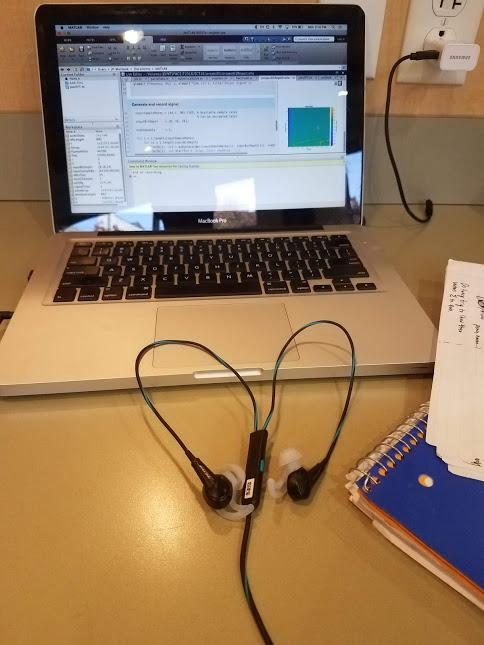

For replicability, let's also generate the sound using Matlab. Let's try an LFM chirp. We now have further unkowns (system record and 

Max audio-settings, 24-bit, 96 kHz

Note one speaker on my mac is broken, I believe only a tweeter is functional 



% Set up signal
fSampleOut = 44.1E3; 
signalTime = 1; % second
fVec       = [1000, 4000]; % from 100 Hz to 4 kHz
timeArray  = 0:(1/fSampleOut):signalTime; % Time (seconds)
fArray     = linspace(fVec(1), fVec(2), length(timeArray) );  
nBitsOut   = 24; 
y          = chirp(timeArray, fVec(1), timeArray(end), fVec(end)); 

Verifying output signal

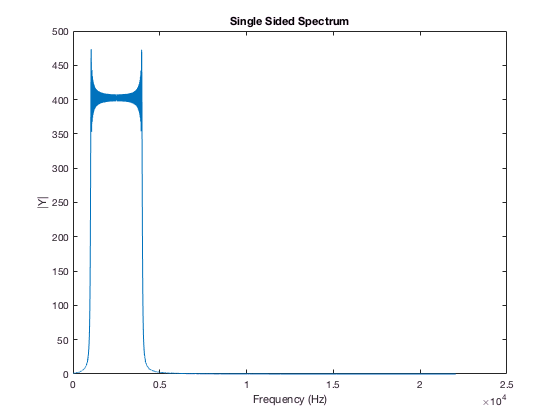

Y = fftshift(abs(fft(y)));
Y = Y(round(length(Y)/2):end); % Round signal if odd length
f = linspace(0, fSampleOut/2, length(Y)); 
plot(f, Y); xlabel('Frequency (Hz)'); ylabel('|Y|'); title('Single Sided Spectrum'); 

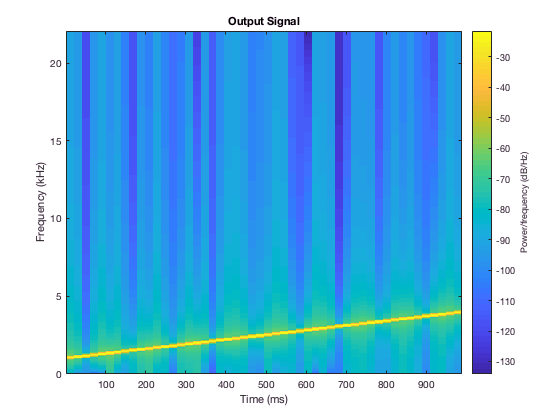


windowLength = 20E-3.*fSampleOut; 
dftLength = windowLength;
spectrogram(y, windowLength, round(0.01*windowLength), dftLength, fSampleOut, 'yaxis')
%ylabel('Frequency (Hz)'); xlabel('Time (s)');
title('Output Signal'); 

## Generate and record signal

inputSampleRates = [44.1, 96].*1E3; % Available sample rates
                                    % Can be decimated later
inputBitDepth    = [24, 16, 24];

numChannels      = 1; 

for i = 1:length(inputSampleRates)  
    for ii = 1:length(inputBitDepth)
        recObj{i, ii} = audiorecorder(inputSampleRates(i), inputBitDepth(ii), numChannels); 
        recObj{i, ii}.StartFcn = 'disp(''Start speaking.'')';
        recObj{i, ii}.StopFcn = 'disp(''End of recording.'')';
    end
end

record(recObj{1,1}, 3);

Start speaking.


tic;
while toc < 2
    sound(y, fSampleOut); pause(signalTime.*0.9); 
end
audioData{1, 1} = getaudiodata(recObj{1,1}); 


## Signal Processing on Recorded signal


y = audioData{1,1};

windowLength = 20E-3.*inputSampleRates(1); 
unitWindow       = ones(windowLength, 1);
dftLength    = windowLength;

The following spectrograms compare the overlap (L) and window properties

- Hamming vs unit-step

- Full overlap (L=1) vs. no overlap

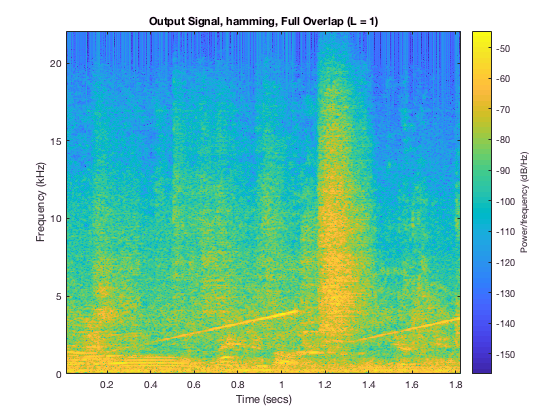

figure; 
[fbs.ham.s, fbs.ham.w.fbs, fbs.ham.t] =  spectrogram(y, windowLength, windowLength-1, dftLength, inputSampleRates(1), 'yaxis');
spectrogram(y, windowLength, windowLength-1, dftLength, inputSampleRates(1), 'yaxis'); % For display
%ylabel('Frequency (Hz)'); xlabel('Time (s)'); 
title('Output Signal, hamming, Full Overlap (L = 1)'); 

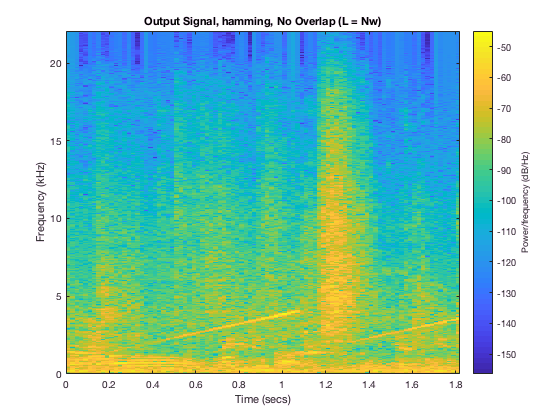


figure;
[gfbs.ham.s, gfbs.ham.w.fbs, gfbs.ham.t] =  spectrogram(y, windowLength, 0, dftLength, inputSampleRates(1), 'yaxis');
spectrogram(y, windowLength, 0, dftLength, inputSampleRates(1), 'yaxis');
%ylabel('Frequency (Hz)'); xlabel('Time (s)'); 
title('Output Signal, hamming, No Overlap (L = Nw)'); 

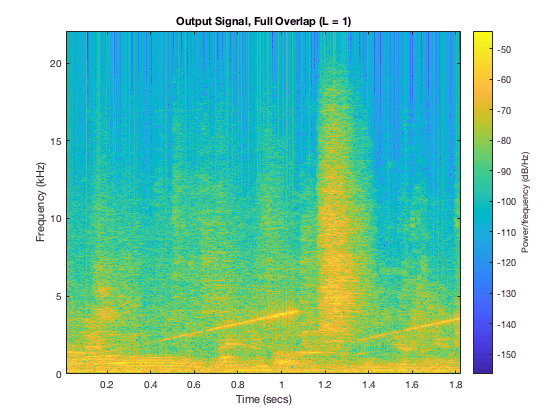


[fbs.UnitStep.s, fbs.UnitStep.w.fbs, fbs.UnitStep.t] =  spectrogram(y, unitWindow, windowLength-1, dftLength, inputSampleRates(1), 'yaxis');
spectrogram(y, unitWindow, windowLength-1, dftLength, inputSampleRates(1), 'yaxis');
%ylabel('Frequency (Hz)'); xlabel('Time (s)');
title('Output Signal, Full Overlap (L = 1)'); 

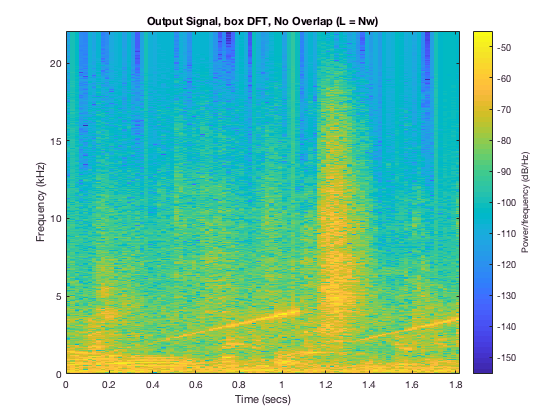


figure;
[gfbs.UnitStep.s, gfbs.UnitStep.w.fbs, gfbs.UnitStep.t] =  spectrogram(y, unitWindow, 0, dftLength, inputSampleRates(1), 'twosided','yaxis');
spectrogram(y, unitWindow, 0, dftLength, inputSampleRates(1), 'yaxis');
%ylabel('Frequency (Hz)'); xlabel('Time (s)'); 
title('Output Signal, box window, No Overlap (L = Nw)'); 

We observe more frequency blurring with the unit step (sharp increases at the start of signal). 

We observe a smoother signal with more overlap (computing fft for every point. 

## Implimenting GFBS Method

First, we must verify the GFBS conditions are satisfied. 

L is defined by window overlap...

Number of overlapped samples, specified as a positive integer.

- If [`window`](https://www.mathworks.com/help/signal/ref/spectrogram.html#bultmx7-window) is scalar, then `noverlap` must be smaller than `window`.

- If `window` is a vector, then `noverlap` must be smaller than the length of `window`.

M is defined by the DFT length. We have purposefully set these parameters equal so that we have critical sampling in at least one case. 

The critically sampled case / unit step makes it very simple to reconstruct using f[n] = 1/w[n] = w[n]

j = sqrt(-1);  
[M, L] = size(gfbs.UnitStep.s); 
Nw   = M; % Critically sampled
sum1 = zeros(1, length(y)); 
exponentialPart = @(k) (exp(j.*(2.*pi.*(k-1)./M) .* (0:(Nw-1)) ) );
% for i = 1:length(dtftDims(2)) 
%%% f[n-iL] == for all 0, i ~= 0
tempSum = zeros(1, M);
tic;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% IMPLIMENT THIS USING FFT %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for ll = 1:floor(length(y)/windowLength)
    indices = ((ll-1)*windowLength+1):((ll)*windowLength) ;
    temp    = zeros(1,M); 
    tempNew = zeros(1,M);
    for k = 1:(M) % Matlab arrays start at 1
        tempNew = (gfbs.UnitStep.s(k,ll).* exponentialPart(k) ); % .*(n - iL); 
        temp    = temp+tempNew;
        tempNew = zeros(1, M);
    end
    sum1(indices) = temp;
end
sum1 = (1./M).* sum1; 
fprintf('HOLY SH*T IT WORKED, only took %01.0f seconds... wowzers', toc)

HOLY SH*T IT WORKED, only took 90 seconds... wowzers

## Analyze Results

disp('Test for numerical errors, max of real, imag'); 

Test for numerical errors, max of real, imag



% This test seems kind of hand-wavy
fprintf('Real component is %01.1f orders of magnitude above imaginary', log10(max(real(sum1))/max(imag(sum1)))); 

Real component is 12.7 orders of magnitude above imaginary

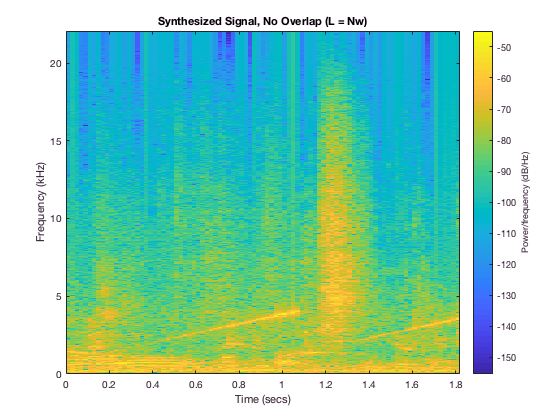

if log10(max(real(sum1))/max(imag(sum1))) < 10
    disp('Signal may not be real (Synthesis algorithm is incorrect)'); 
end

sound(real(sum1)./max(real(sum1)), inputSampleRates(1));

spectrogram(real(sum1),    unitWindow,   0,                 dftLength, inputSampleRates(1), 'onesided','yaxis');
%           signal   window shape  overlap (0 = none), fSamples, signal sample rate,   frequency axis
% ylabel('Frequency (Hz)'); xlabel('Time (s)'); 
title('Synthesized Signal, No Overlap (L = Nw)'); 

Trust me, they sound really similar... Compare synthesized signal spectrogram w/ Box Window, no overlap